# Sonar

## descargar datos

[https://www.mediafire.com/file/m8qct204rfsm45m/Datos.rar/file](https://www.mediafire.com/file/m8qct204rfsm45m/Datos.rar/file)

## importar datos

[https://www.youtube.com/watch?v=7dwNmUft4gE&list=PLg0Uook28IlczPTfmlmQ_EHndY8gbLkTQ&index=1](https://www.youtube.com/watch?v=7dwNmUft4gE&list=PLg0Uook28IlczPTfmlmQ_EHndY8gbLkTQ&index=1)

los datos son importados facilmente gracias a la funcion importfile creada automaticamente por import data

    entradas

        ubicacion de la base de datos 'Datos\sonar.tot'

        fila inicial '1'

        fila final '2288'

    salidas

        base de datos DESORDENADA "sonarDesordenada"

clear
close
clc
sonarDesordenada = importfile('Datos\sonar.tot', 1, 2288)

sonarDesordenada =          0       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0491    0.0279    0.0592    0.1270    0.1772    0.1908       NaN       NaN
    0.2217    0.0768    0.1246    0.2028    0.0947    0.2497       NaN       NaN
    0.2209    0.3195    0.3340    0.3323    0.2780    0.2975       NaN       NaN
    0.2948    0.1729    0.3264    0.3834    0.3523    0.5410       NaN       NaN
    0.5228    0.4475    0.5340    0.5323    0.3907    0.3456       NaN       NaN
    0.4091    0.4639    0.5580    0.5727    0.6355    0.7563       NaN       NaN
    0.6903    0.6176    0.5379    0.5622    0.6508    0.4797       NaN       NaN
    0.3736    0.2804    0.1982    0.2438    0.1789    0.1706       NaN       NaN
    0.0762    0.0238    0.0268    0.0081    0.0129    0.0161       NaN       NaN


## Ordenar datos

[https://www.youtube.com/watch?v=hwQC7Vlw4IA&list=PLg0Uook28IlczPTfmlmQ_EHndY8gbLkTQ&index=2](https://www.youtube.com/watch?v=hwQC7Vlw4IA&list=PLg0Uook28IlczPTfmlmQ_EHndY8gbLkTQ&index=2)

    entradas

        base de datos desordenada "sonarDesordenada"

    salidas

        base de datos ordenada "sonarOrdenada"

sonarOrdenada = ordenardataBase(sonarDesordenada)

sonarOrdenada =     0.0491    0.0279    0.0592    0.1270    0.1772    0.1908    0.2217    0.0768    0.1246    0.2028    0.0947    0.2497    0.2209    0.3195    0.3340    0.3323    0.2780    0.2975    0.2948    0.1729    0.3264    0.3834    0.3523    0.5410    0.5228    0.4475    0.5340    0.5323    0.3907    0.3456    0.4091    0.4639    0.5580    0.5727    0.6355    0.7563    0.6903    0.6176    0.5379    0.5622    0.6508    0.4797    0.3736    0.2804    0.1982    0.2438    0.1789    0.1706    0.0762    0.0238
    0.0200    0.0371    0.0428    0.0207    0.0954    0.0986    0.1539    0.1601    0.3109    0.2111    0.1609    0.1582    0.2238    0.0645    0.0660    0.2273    0.3100    0.2999    0.5078    0.4797    0.5783    0.5071    0.4328    0.5550    0.6711    0.6415    0.7104    0.8080    0.6791    0.3857    0.1307    0.2604    0.5121    0.7547    0.8537    0.8507    0.6692    0.6097    0.4943    0.2744    0.0510    0.2834    0.2825    0.4256    0.2641    0.1386    0.1051    0.1343   

## Configurar un solo Target

se elimina la ultima columna [62] de la base de datos ordenada por que no se necesita debido a que es exactamente la inversa de la columna [61]

sonarOrdenada(:,62)=[]

sonarOrdenada =     0.0491    0.0279    0.0592    0.1270    0.1772    0.1908    0.2217    0.0768    0.1246    0.2028    0.0947    0.2497    0.2209    0.3195    0.3340    0.3323    0.2780    0.2975    0.2948    0.1729    0.3264    0.3834    0.3523    0.5410    0.5228    0.4475    0.5340    0.5323    0.3907    0.3456    0.4091    0.4639    0.5580    0.5727    0.6355    0.7563    0.6903    0.6176    0.5379    0.5622    0.6508    0.4797    0.3736    0.2804    0.1982    0.2438    0.1789    0.1706    0.0762    0.0238
    0.0200    0.0371    0.0428    0.0207    0.0954    0.0986    0.1539    0.1601    0.3109    0.2111    0.1609    0.1582    0.2238    0.0645    0.0660    0.2273    0.3100    0.2999    0.5078    0.4797    0.5783    0.5071    0.4328    0.5550    0.6711    0.6415    0.7104    0.8080    0.6791    0.3857    0.1307    0.2604    0.5121    0.7547    0.8537    0.8507    0.6692    0.6097    0.4943    0.2744    0.0510    0.2834    0.2825    0.4256    0.2641    0.1386    0.1051    0.1343   

## Separar roca y metal

[https://www.youtube.com/watch?v=5f6VOCPxICI&list=PLg0Uook28IlczPTfmlmQ_EHndY8gbLkTQ&index=9](https://www.youtube.com/watch?v=5f6VOCPxICI&list=PLg0Uook28IlczPTfmlmQ_EHndY8gbLkTQ&index=9)

    entradas

        base de datos ordenada "sonarOrdenada"

        numero de Rocas "97"

        numero de Metales "111"

        Target "61"

    salidas

        base de datos de Rocas "Roca"

        base de datos de Metal "Metal"

[Roca,Metal]= separarTargets(sonarOrdenada,97,111,61)

Roca =     0.0200    0.0371    0.0428    0.0207    0.0954    0.0986    0.1539    0.1601    0.3109    0.2111    0.1609    0.1582    0.2238    0.0645    0.0660    0.2273    0.3100    0.2999    0.5078    0.4797    0.5783    0.5071    0.4328    0.5550    0.6711    0.6415    0.7104    0.8080    0.6791    0.3857    0.1307    0.2604    0.5121    0.7547    0.8537    0.8507    0.6692    0.6097    0.4943    0.2744    0.0510    0.2834    0.2825    0.4256    0.2641    0.1386    0.1051    0.1343    0.0383    0.0324
    0.0453    0.0523    0.0843    0.0689    0.1183    0.2583    0.2156    0.3481    0.3337    0.2872    0.4918    0.6552    0.6919    0.7797    0.7464    0.9444    1.0000    0.8874    0.8024    0.7818    0.5212    0.4052    0.3957    0.3914    0.3250    0.3200    0.3271    0.2767    0.4423    0.2028    0.3788    0.2947    0.1984    0.2341    0.1306    0.4182    0.3835    0.1057    0.1840    0.1970    0.1674    0.0583    0.1401    0.1628    0.0621    0.0203    0.0530    0.0742    0.0409  

Metal =     0.0491    0.0279    0.0592    0.1270    0.1772    0.1908    0.2217    0.0768    0.1246    0.2028    0.0947    0.2497    0.2209    0.3195    0.3340    0.3323    0.2780    0.2975    0.2948    0.1729    0.3264    0.3834    0.3523    0.5410    0.5228    0.4475    0.5340    0.5323    0.3907    0.3456    0.4091    0.4639    0.5580    0.5727    0.6355    0.7563    0.6903    0.6176    0.5379    0.5622    0.6508    0.4797    0.3736    0.2804    0.1982    0.2438    0.1789    0.1706    0.0762    0.0238
    0.1313    0.2339    0.3059    0.4264    0.4010    0.1791    0.1853    0.0055    0.1929    0.2231    0.2907    0.2259    0.3136    0.3302    0.3660    0.3956    0.4386    0.4670    0.5255    0.3735    0.2243    0.1973    0.4337    0.6532    0.5070    0.2796    0.4163    0.5950    0.5242    0.4178    0.3714    0.2375    0.0863    0.1437    0.2896    0.4577    0.3725    0.3372    0.3803    0.4181    0.3603    0.2711    0.1653    0.1951    0.2811    0.2246    0.1921    0.1500    0.0665 

## Medidas Estadisticas

media= nanmean();

desviacionEstandar= nanstd();

Varianza= nanvar();

IQR= iqr();

Skewness= skewness();

Kurtosis= kurtosis();

medidasEstadisticas_Roca = tablaMedidasEstadisticas(Roca(:,1:60))

medidasEstadisticas_Roca =     0.0225    0.0303    0.0360    0.0414    0.0620    0.0962    0.1142    0.1176    0.1374    0.1593    0.1747    0.1916    0.2262    0.2690    0.3076    0.3756    0.4171    0.4482    0.4668    0.5002    0.5423    0.5693    0.6130    0.6538    0.6688    0.6928    0.6877    0.6731    0.6327    0.5799    0.5298    0.4516    0.4408    0.4457    0.4555    0.4607    0.4173    0.3489    0.3137    0.3181    0.2854    0.2523    0.2118    0.1751    0.1423    0.1169    0.0945    0.0695    0.0384    0.0178
    0.0147    0.0240    0.0291    0.0312    0.0472    0.0650    0.0652    0.0798    0.0999    0.1132    0.1134    0.1347    0.1381    0.1663    0.2191    0.2554    0.2900    0.2698    0.2584    0.2594    0.2488    0.2606    0.2439    0.2332    0.2500    0.2388    0.2200    0.2059    0.2345    0.2334    0.2016    0.2132    0.2171    0.2513    0.2612    0.2623    0.2430    0.2238    0.2162    0.1968    0.1772    0.1659    0.1303    0.1074    0.0957    0.0938    0.0678  

medidasEstadisticas_Metal = tablaMedidasEstadisticas(Metal(:,1:60))

medidasEstadisticas_Metal =     0.0350    0.0455    0.0507    0.0648    0.0867    0.1119    0.1284    0.1498    0.2135    0.2510    0.2896    0.3015    0.3144    0.3207    0.3312    0.3810    0.4150    0.4559    0.5381    0.6179    0.6674    0.6723    0.6767    0.6892    0.6812    0.7061    0.7148    0.7123    0.6503    0.5818    0.4824    0.4280    0.3966    0.3661    0.3376    0.3186    0.3170    0.3316    0.3364    0.3052    0.2926    0.3010    0.2769    0.2481    0.2452    0.1988    0.1469    0.1106    0.0637    0.0227
    0.0271    0.0378    0.0440    0.0545    0.0598    0.0526    0.0582    0.0872    0.1222    0.1374    0.1254    0.1241    0.1307    0.1597    0.1931    0.2119    0.2397    0.2553    0.2541    0.2541    0.2524    0.2428    0.2528    0.2440    0.2414    0.2368    0.2664    0.2610    0.2459    0.2102    0.2228    0.2136    0.1955    0.2062    0.2455    0.2484    0.2281    0.2037    0.1831    0.1618    0.1663    0.1687    0.1398    0.1444    0.1741    0.1514    0.0945 

## BOXPLOT

###     Metal

figure(1)
boxplot(Metal(:,1:60),"Colors","g")

###     Roca

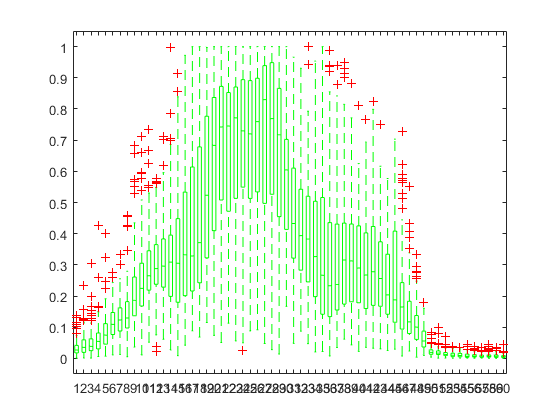

figure(2)
boxplot(Roca(:,1:60),"Colors","b")

###     Superpuestas

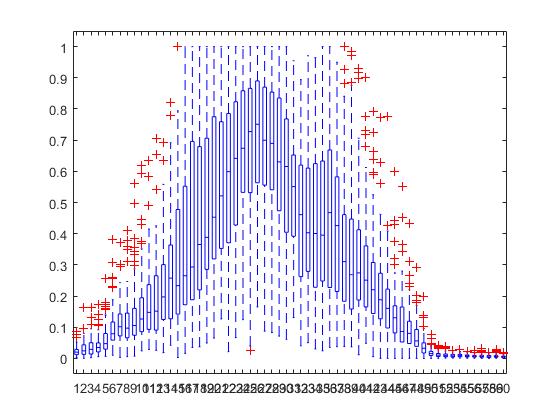

figure(3)
boxplot(Metal(:,1:60),"Colors","g")

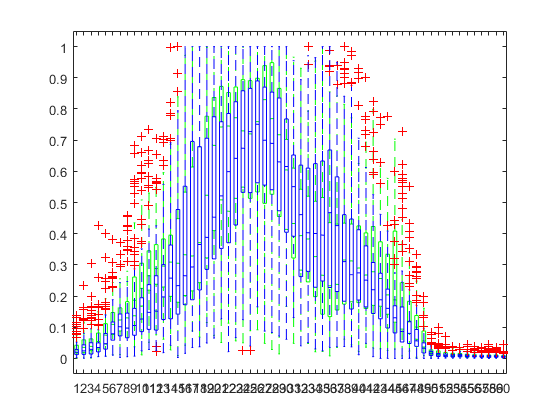

hold on
boxplot(Roca(:,1:60),"Colors","b")
hold off

## Plot

###     Metal

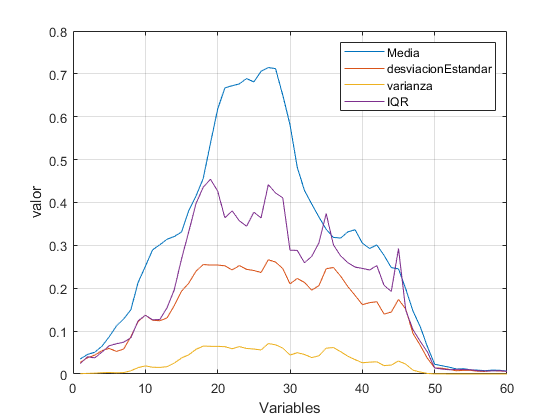

figure(4)
plot(medidasEstadisticas_Metal(1,:),'DisplayName','Media')
hold on
plot(medidasEstadisticas_Metal(2,:),'DisplayName','desviacionEstandar')
plot(medidasEstadisticas_Metal(3,:),'DisplayName','varianza')
plot(medidasEstadisticas_Metal(4,:),'DisplayName','IQR')
hold off
xlim([0.0 60.0])
ylim([0.000 0.800])
grid on
legend('show')
xlabel('Variables')
ylabel('valor')

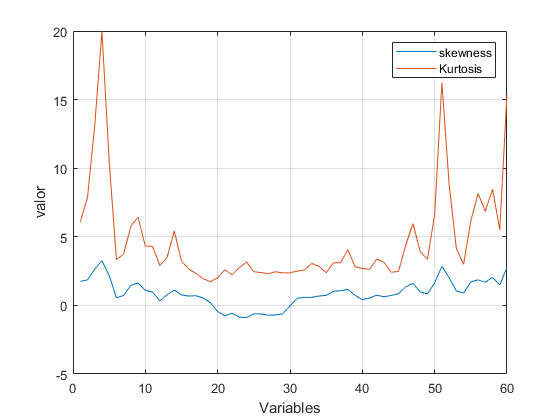


figure(5)
plot(medidasEstadisticas_Metal(5,:),'DisplayName','skewness')
hold on
plot(medidasEstadisticas_Metal(6,:),'DisplayName','Kurtosis')
hold off
grid on
legend('show')
xlabel('Variables')
ylabel('valor')